## Load Training Data

clear all;
%input = csvread('BioMetric_ECG_Unique.csv',1,0);
input = csvread('BioMetric_ECG_V3_10participants.csv',1,0);
%fileID = fopen('BioMetric_ECG_Unique.txt');
fileID = fopen('BioMetric_ECG_V3_Labels.txt');
target1 = textscan(fileID,'%s');
fclose(fileID);
%input_cell = zeros;
%disp(size(input,1))

%For training take 60 seconds of data ( 60 sec * 100 Hz = 6000 entries )
trainingInput = input(1001:7000,:)';
%For testing take 10 seconds of data
testInput     = input(16001:22000,:)';

input_cell = cell(size(trainingInput,1),1);
for i=1:(size(trainingInput,1))
	input_cell{i,1} = trainingInput(i,:);
end	

target = categorical(target1{1,1});

XTrain = input_cell;
YTrain = target;



## Load Test Data

XTest = testInput;

XTest_cell = cell(size(XTest,1),1);
for i=1:(size(XTest,1))
	XTest_cell{i,1} = XTest(i,:);
end	

XTest = XTest_cell;
%YTest = categorical(YTest);
YTest = target;

## Extracting features from the Signal ( Instantaneous Frequency and Spectral Entropy)

The instantaneous frequency is a useful concept for describing non-monochromatic signals. 

%fs is how many data points would be considered for a feature map to check spikes in signal
fs = 100;
%Use cellfun to apply the instfreq function to every cell in the training and testing sets.
instfreqTrain = cellfun(@(x)instfreq(x,fs)',XTrain,'UniformOutput',false);
instfreqTest = cellfun(@(x)instfreq(x,fs)',XTest,'UniformOutput',false);
%Use cellfun to apply the pentropy function to every cell in the training and testing sets.
pentropyTrain = cellfun(@(x)pentropy(x,fs)',XTrain,'UniformOutput',false);
pentropyTest = cellfun(@(x)pentropy(x,fs)',XTest,'UniformOutput',false);
% Concatenate the features such that each cell in the new training and testing 
% sets has two dimensions, or two features.
XTrain2 = cellfun(@(x,y)[x;y],instfreqTrain,pentropyTrain,'UniformOutput',false);
XTest2 = cellfun(@(x,y)[x;y],instfreqTest,pentropyTest,'UniformOutput',false);

%XTrain2(1:5)

XV = [XTrain2{:}];
mu = mean(XV,2);
sg = std(XV,[],2);

XTrainSD = XTrain2;
XTrainSD = cellfun(@(x)(x-mu)./sg,XTrainSD,'UniformOutput',false);

XTestSD = XTest2;
XTestSD = cellfun(@(x)(x-mu)./sg,XTestSD,'UniformOutput',false);

%instFreqNSD = XTrainSD{1}(1,:)
%pentropyNSD = XTrainSD{1}(2,:)

## Setup LSTM (Recurrent Neural Network) Architecture

**Classification LSTM Networks**

To create an LSTM network for sequence-to-label classification, create a  layer array containing a sequence input layer, an LSTM layer, a fully  connected layer, a softmax layer, and a classification output layer.

Set the size of the sequence input layer to the number of features of the  input data. Set the size of the fully connected layer to the number of  classes. You do not need to specify the sequence length.

For the LSTM layer, specify the number of hidden units and the output mode `'last'`

% Two features are extracted from the time signal
features = 2;
numHiddenUnits = 10;
% There are 2 types of classess 
numClasses = 2;

layers = [ ...
    sequenceInputLayer(features)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer
    ];

layers

layers =   5x1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 2 dimensions
     2   ''   LSTM                    LSTM with 10 hidden units
     3   ''   Fully Connected         2 fully connected layer
     4   ''   Softmax                 softmax
     5   ''   Classification Output   crossentropyex

## Setup Training Options


maxEpochs = 50;
miniBatchSize = 1;
%sequenceLength = 100;
initialLearnRate = 0.01;

%% Make Sure Solver is 'sgdm' as 'adam' does not provide good result %%
options = trainingOptions('adam', ...
    'ExecutionEnvironment','auto', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize', miniBatchSize, ...
    'InitialLearnRate', initialLearnRate, ...
    'GradientThreshold', 1, ...
    'plots','training-progress', ...
    'Verbose',false);

## Train the Network

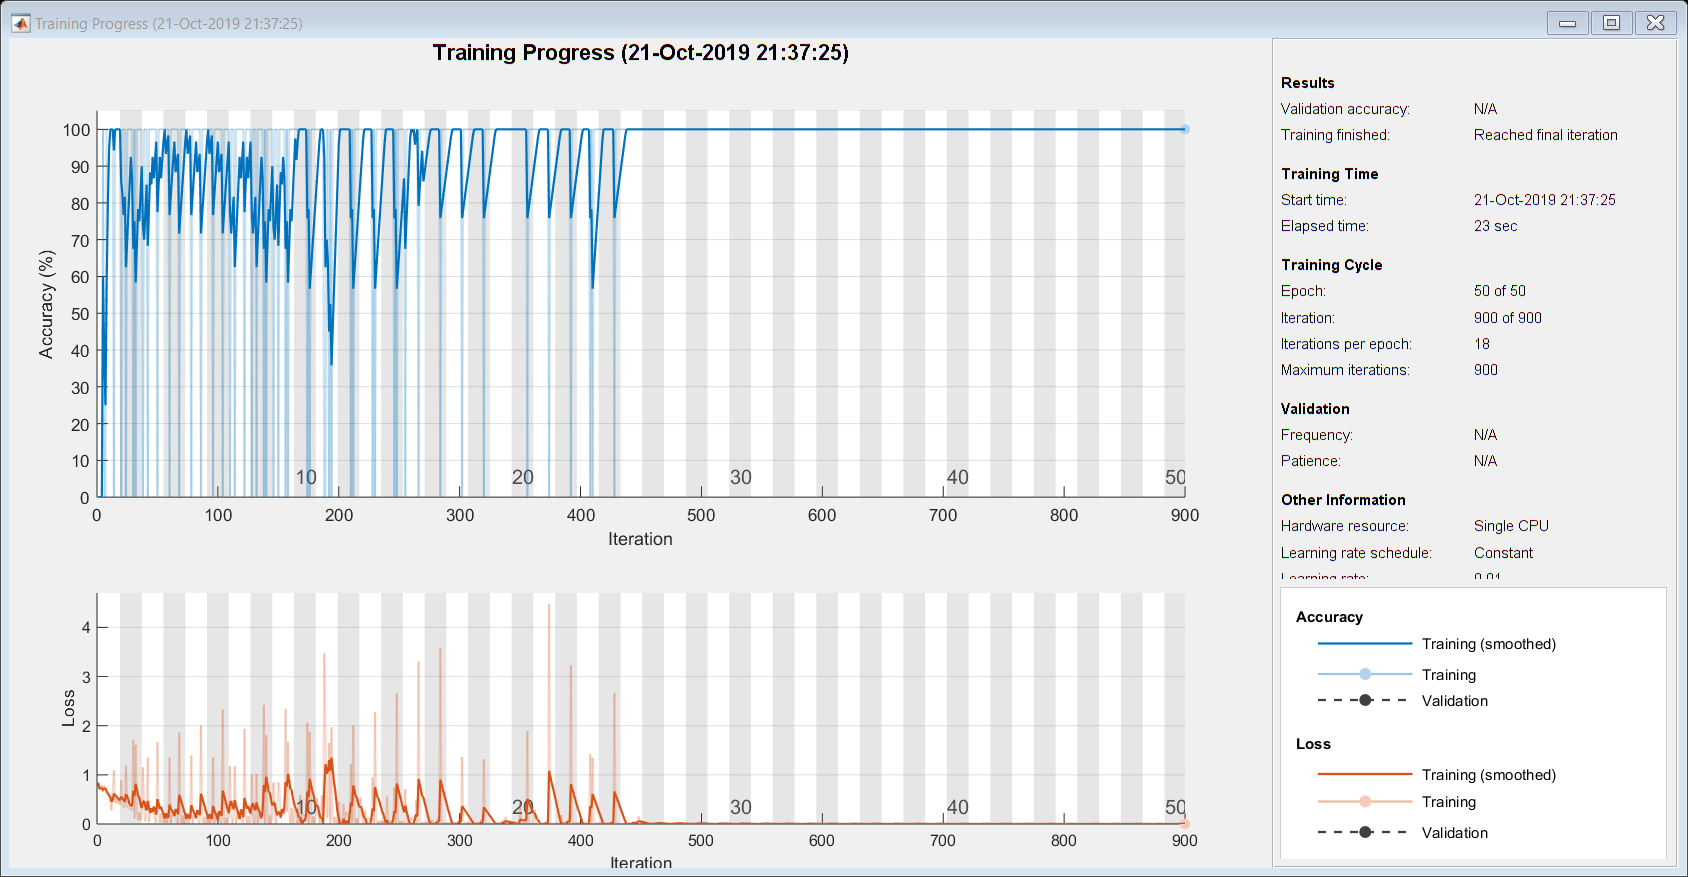

%When we specify 'training-progress' as the 'Plots' value in trainingOptions and start network training, 
% trainNetwork creates a figure and displays training metrics at every iteration
net = trainNetwork(XTrainSD,YTrain,layers,options);

## **Calculate the classification accuracy of the predictions**

% numObservationsTest = numel(XTest);
% for i=1:numObservationsTest
%     sequence = XTest{i};
%     sequenceLengthsTest(i) = size(sequence,2);
% end
% [sequenceLengthsTest,idx] = sort(sequenceLengthsTest);
% XTest = XTest(idx);
% YTest = YTest(idx);
% YPred = classify(net,XTest, ...
%     'MiniBatchSize',miniBatchSize, ...
%     'SequenceLength','longest');
% 
% acc = sum(YPred == YTest)./numel(YTest)



## Check the Network on Training set .

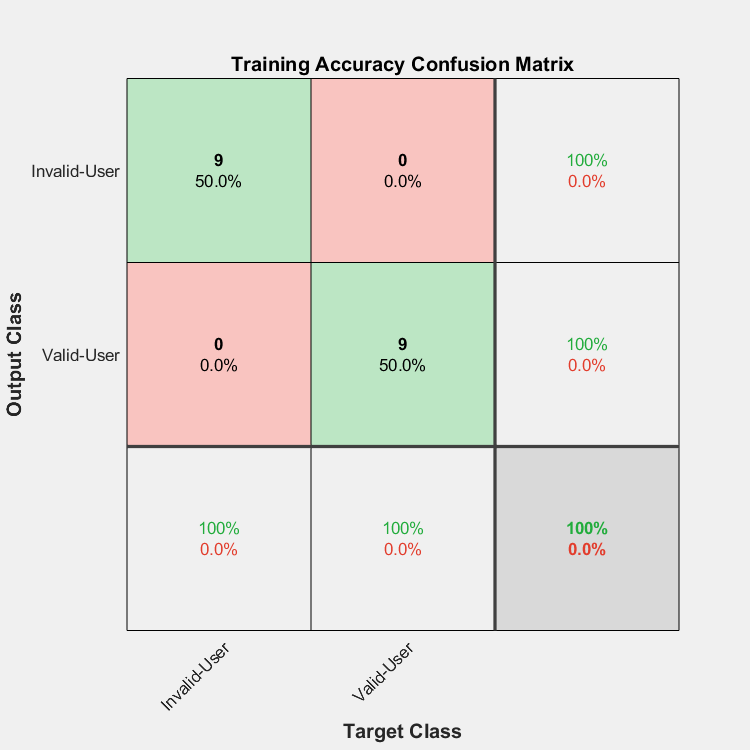

trainPred2 = classify(net,XTrainSD);
figure
plotconfusion(YTrain',trainPred2','Training Accuracy')

## Check the Network on Testing set

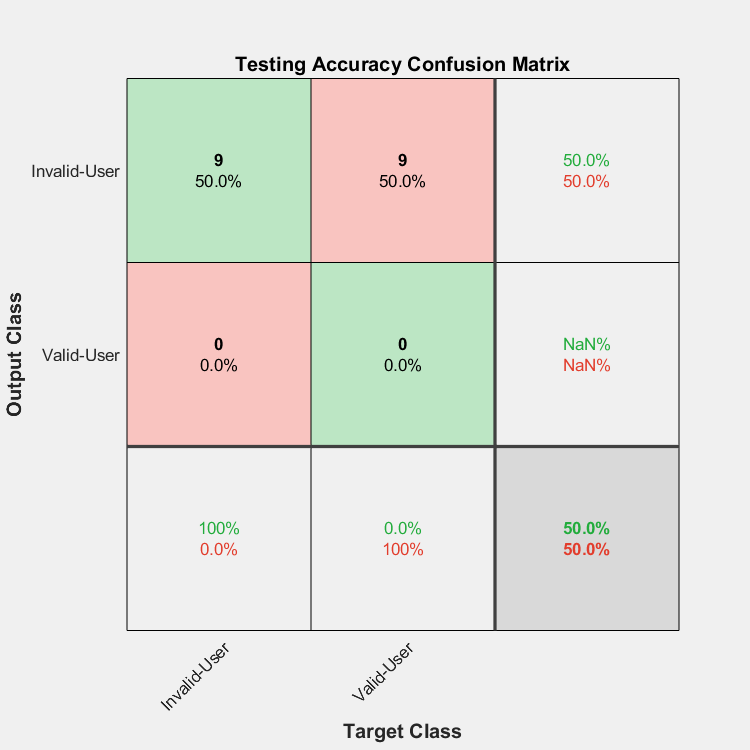

testPred2 = classify(net,XTestSD);
figure
plotconfusion(YTest',testPred2','Testing Accuracy')